clear
% Mean and Covariance for X
mu_x = [2;5];
sigma2_x = randn(2);
n=size(mu_x,1)

n = 2

% Mean of noise r
mu_r = [0;0];
% Measurement noise covariance
sigma2_r = randn(2);
A=eye(n);
B=eye(n);

% Mean and cov of y
mu_y = A*mu_x+B*mu_r

mu_y =      2
     5


Sigma_y=A*sigma2_x*A'+B*sigma2_r*B'

Sigma_y =    -2.3772    1.4790
    1.6605    1.0990


% Mean and covariance of joint Gaussian [x;y]
A_xr2xy  = [eye(n) zeros(n);
             A         B];
b_xr2xy  = zeros(4,1);
% define mean of [x;r] = [E[x] ; E[r]] = [mu_x, mu_r=0]
mu_xr    = [mu_x; mu_r];

% define covariance of [x;r]. Since they are independent, 
% then cov[x;r] = [ cov[x] 0; 0; cov[r] ] = diag(cov[x], cov[r])
Sigma_xr = blkdiag(sigma2_x,sigma2_r);

% calculate mean and cov of the new vector [x;y], which is obtained from a
% linear transformation [x;y] = A*[x;r] + b
[mu, Sigma] = affineGaussianTransform(mu_xr, Sigma_xr, A_xr2xy, b_xr2xy)

mu =      2
     5
     2
     5


Sigma =    -1.1201    1.6555   -1.1201    1.6555
    2.5260    0.3075    2.5260    0.3075
   -1.1201    1.6555   -2.3772    1.4790
    2.5260    0.3075    1.6605    1.0990


mu_p = 5;
sigma2_p = 3;
y = mu_p+5;
sigma2_r = 3;
[mu1,sigma1] = posteriorGaussian(mu_p, sigma2_p, y, sigma2_r)

mu1 = 7.5000

sigma1 = 1.5000

[mu_xy, Sigma_xy] = jointGaussian(mu_p, sigma2_p, sigma2_r)

mu_xy =      5
     5


Sigma_xy =      3     3
     3     6


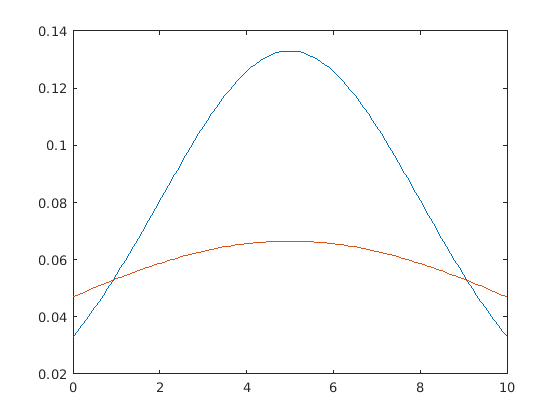

x=0:0.1:10;
y=normpdf(x,mu_xy(1),Sigma_xy(1,1));
plot(x,y)
hold on

x=0:0.1:10;
y=normpdf(x,mu_xy(2),Sigma_xy(2,2));
plot(x,y)


$$p(x,y)= \propto p(x|y)$$


syms mux sx sr x y
[mu_xy, Q_xy] = jointGaussian(mux, sx, sr)

$$mu\_xy = \left(\begin{array}{c} \mathrm{mux}\\ \mathrm{mux} \end{array}\right)$$

$$Q\_xy = \left(\begin{array}{cc} \mathrm{sx} & \mathrm{sx}\\ \mathrm{sx} & \mathrm{sr}+\mathrm{sx} \end{array}\right)$$

syms munew snew c
eqq1 = ([x;y] - mu_xy ).' * Q_xy^-1  * ([x;y] - mu_xy )     

$$eqq1 = -\left(\frac{\mathrm{mux}-x}{\mathrm{sr}}-\frac{\mathrm{mux}-y}{\mathrm{sr}}\right)\,\left(\mathrm{mux}-y\right)-\left(\frac{\mathrm{mux}-y}{\mathrm{sr}}-\frac{\left(\mathrm{sr}+\mathrm{sx}\right)\,\left(\mathrm{mux}-x\right)}{\mathrm{sr}\,\mathrm{sx}}\right)\,\left(\mathrm{mux}-x\right)$$

eqq2 = (  x   - munew ).'  * snew^-1  * (  x   - munew )  + c

$$eqq2 = c+\frac{{\left(\mathrm{munew}-x\right)}^{2}}{\mathrm{snew}}$$

eqq1 - eqq2

$$ans = -c-\left(\frac{\mathrm{mux}-x}{\mathrm{sr}}-\frac{\mathrm{mux}-y}{\mathrm{sr}}\right)\,\left(\mathrm{mux}-y\right)-\left(\frac{\mathrm{mux}-y}{\mathrm{sr}}-\frac{\left(\mathrm{sr}+\mathrm{sx}\right)\,\left(\mathrm{mux}-x\right)}{\mathrm{sr}\,\mathrm{sx}}\right)\,\left(\mathrm{mux}-x\right)-\frac{{\left(\mathrm{munew}-x\right)}^{2}}{\mathrm{snew}}$$

coeffs( eqq1 - eqq2, x)

$$ans = \left(\begin{array}{ccc} -c-\mathrm{mux}\,\left(\frac{\mathrm{mux}-y}{\mathrm{sr}}-\frac{\mathrm{mux}\,\left(\mathrm{sr}+\mathrm{sx}\right)}{\mathrm{sr}\,\mathrm{sx}}\right)-\left(\mathrm{mux}-y\right)\,\left(\frac{\mathrm{mux}}{\mathrm{sr}}-\frac{\mathrm{mux}-y}{\mathrm{sr}}\right)-\frac{{\mathrm{munew}}^{2}}{\mathrm{snew}} & \frac{2\,\mathrm{munew}}{\mathrm{snew}}+\frac{2\,\left(\mathrm{mux}-y\right)}{\mathrm{sr}}-\frac{2\,\mathrm{mux}\,\left(\mathrm{sr}+\mathrm{sx}\right)}{\mathrm{sr}\,\mathrm{sx}} & \frac{\mathrm{sr}+\mathrm{sx}}{\mathrm{sr}\,\mathrm{sx}}-\frac{1}{\mathrm{snew}} \end{array}\right)$$

sol = solve( coeffs( eqq1 - eqq2, x) , [munew snew c])

sol = struct with fields:
    munew: [1×1 sym]
     snew: [1×1 sym]
        c: [1×1 sym]


% % Show results
simplify(sol.munew)  % -> (mux*sr + sx*y)/(sr + sx)

$$ans = \frac{\mathrm{mux}\,\mathrm{sr}+\mathrm{sx}\,y}{\mathrm{sr}+\mathrm{sx}}$$

simplify(sol.snew)   % -> (sr*sx)/(sr + sx)

$$ans = \frac{\mathrm{sr}\,\mathrm{sx}}{\mathrm{sr}+\mathrm{sx}}$$

simplify(sol.c)      % -> (mux - y)^2/(sr + sx)

$$ans = \frac{{\left(\mathrm{mux}-y\right)}^{2}}{\mathrm{sr}+\mathrm{sx}}$$